# Project 1

## Digital Signal Conditioning & Noise Reduction Framework

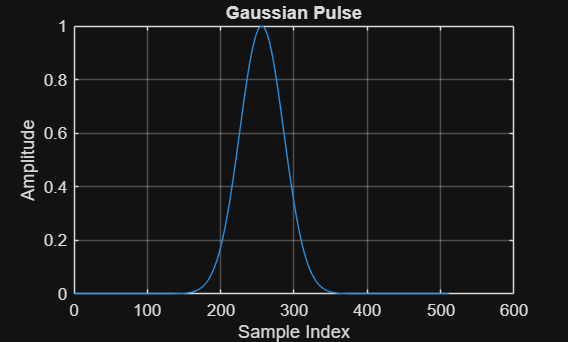

% -----------------------------
% Generate Gaussian Pulse
% -----------------------------

A = 1;           
sigma = 30;     
N = 512;         
n = 0:N-1;     
no = N/2;        
fs = 1000;          

x_n = A * exp(- (n - no).^2 / (2 * sigma^2)); 

figure; 
plot(n, x_n);
xlabel('Sample Index');
ylabel('Amplitude');
title('Gaussian Pulse');
grid on;

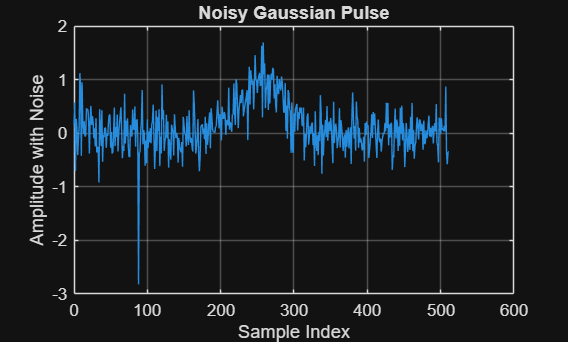


% -----------------------------
% Adding Noise 
% -----------------------------

% Gausian Noise
ISNR = 0.25;
Ps = 1/N * sum(x_n.^2);
Pn = Ps/ 10^(ISNR/10);
w_n = sqrt(Pn)*randn(size(x_n));

% Impulse Noise
p = 0.005;
b = rand(1,N) < p; 
sigma_n = sqrt(Pn);
Ai = 15 * sigma_n * randn(1,N);
w_i = b .* Ai;

y_n = x_n + w_n + w_i;

figure;
plot(n, y_n);
xlabel('Sample Index');
ylabel('Amplitude with Noise');
title('Noisy Gaussian Pulse');
grid on;

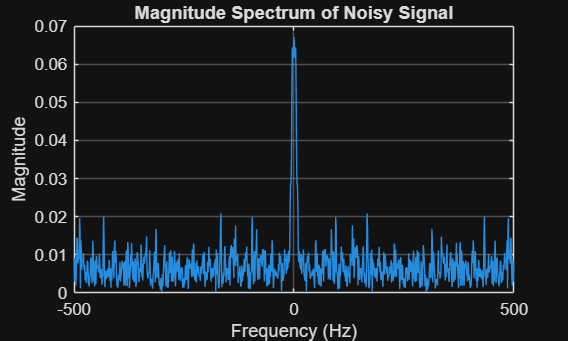


% -----------------------------
% Analysis of Noisy Signal
% -----------------------------

N_fft = 1024;
Y_k = fft(y_n,N_fft);       % FFT with zero padding
f = (-N_fft/2 : N_fft/2 - 1)* fs/N_fft;     % Frequency Axis
Y_k_shift = fftshift(Y_k);  % Shifting of FFT
Mag_Y_k = abs(Y_k_shift)/N_fft;   % Normalized Magnitude Spectrum

% --------------------------------------------------
% Plot the magnitude spectrum of the noisy signal
% -------------------------------------------------- 

figure;
plot(f, (Mag_Y_k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum of Noisy Signal');
grid on;


% Median Filtering
y_n_med = medfilt1(y_n, 5);

% Design FIR Filters
fs = 1000;
fc = 100;
Nf = 51;
n_f = 0:Nf-1;
a = 0.5*(Nf-1);
L = length(x_n); 

fcn = fc / (fs/2);    % Normalizing Cutoff frequency

hn = 2*fcn * sinc(2*fcn * (n_f - a));    % sinc function 

% Check the noise levels
fprintf('\n=== DIAGNOSTIC INFO ===\n');


=== DIAGNOSTIC INFO ===


fprintf('Clean signal max amplitude: %.4f\n', max(abs(x_n)));

Clean signal max amplitude: 1.0000


fprintf('Noisy signal max amplitude: %.4f\n', max(abs(y_n)));

Noisy signal max amplitude: 2.8234


fprintf('Median filtered max amplitude: %.4f\n', max(abs(y_n_med)));

Median filtered max amplitude: 1.3043


fprintf('Number of impulses added: %d\n', sum(b));

Number of impulses added: 1


fprintf('Filter cutoff frequency: %d Hz\n', fc);

Filter cutoff frequency: 100 Hz


fprintf('Filter order: %d\n', Nf);

Filter order: 51


fprintf('========================\n');

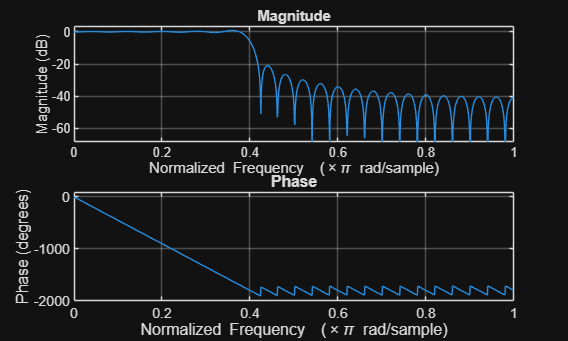



% Rectangular Window
w_rect = rectwin(Nf)';
hn_rect = hn .* w_rect;     
hn_rect = hn_rect/sum(hn_rect); % Normalizing
freqz(hn_rect, 1, 1024);

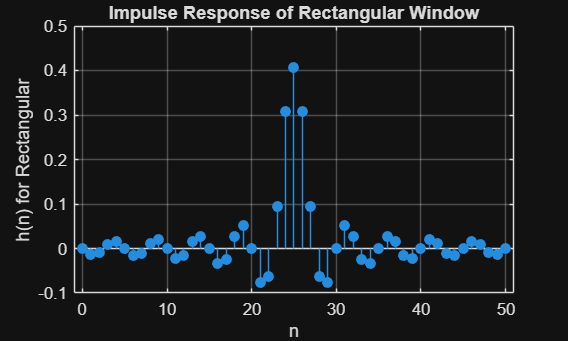


n = 0:length(hn_rect)-1;
stem(n, hn_rect, 'filled')
xlabel('n')
ylabel('h(n) for Rectangular')
title('Impulse Response of Rectangular Window')
grid on

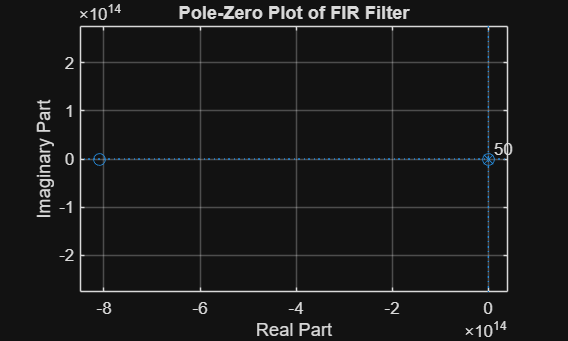


zplane(hn_rect, 1)
title('Pole-Zero Plot of FIR Filter')
grid on

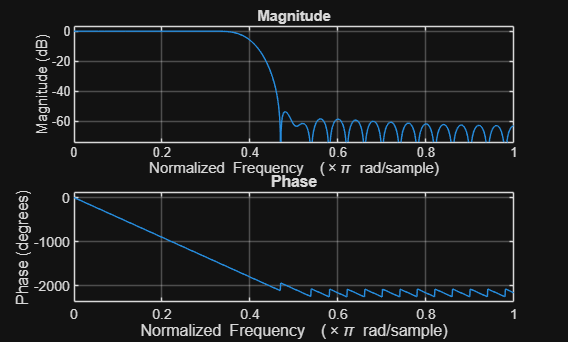


% Hamming Window
w_hamm = hamming(Nf)';     
hn_hamm = hn .* w_hamm;     
hn_hamm = hn_hamm/sum(hn_hamm); % Normalizing
freqz(hn_hamm, 1, 1024);

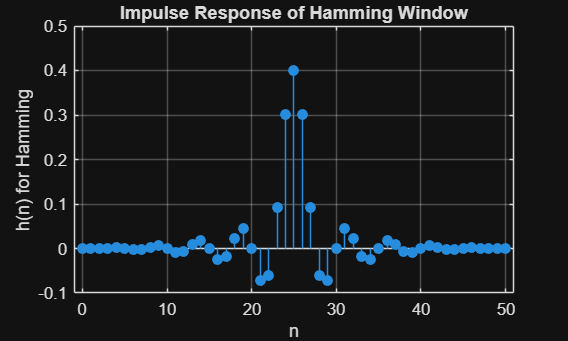


n = 0:length(hn_hamm)-1;
stem(n, hn_hamm, 'filled')
xlabel('n')
ylabel('h(n) for Hamming')
title('Impulse Response of Hamming Window')
grid on

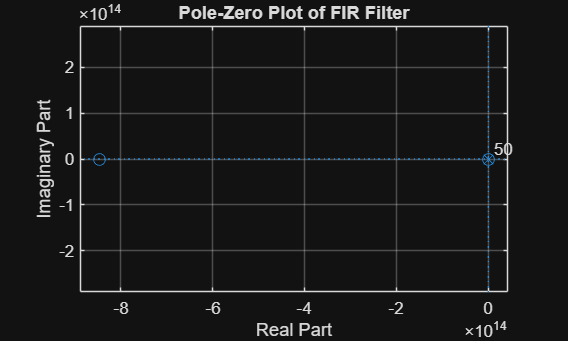


zplane(hn_hamm, 1)
title('Pole-Zero Plot of FIR Filter')
grid on

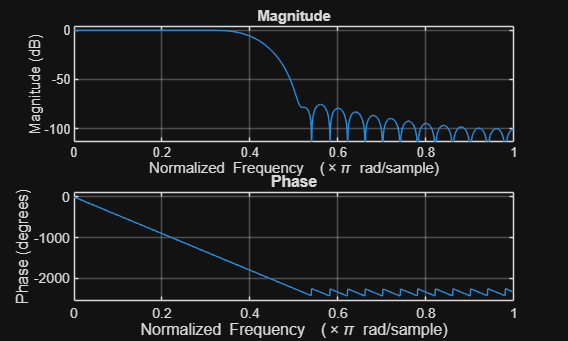


% Blackmann Window
w_black = blackman(Nf)';   
hn_black = hn .* w_black;   
hn_black = hn_black/sum(hn_black); % Normalizing
freqz(hn_black, 1, 1024);

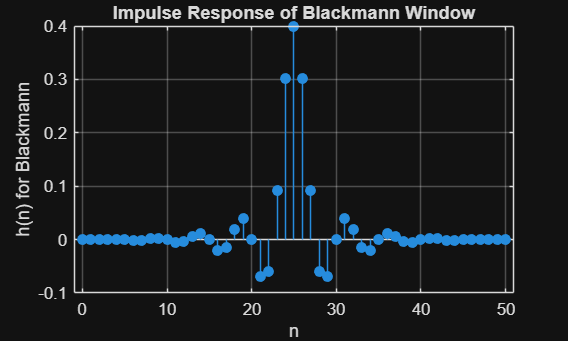


n = 0:length(hn_black)-1;
stem(n, hn_black, 'filled')
xlabel('n')
ylabel('h(n) for Blackmann')
title('Impulse Response of Blackmann Window')
grid on

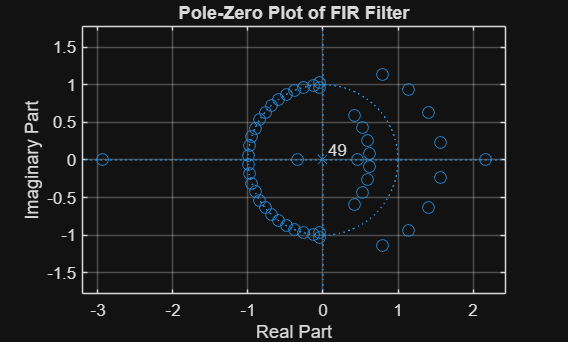


zplane(hn_black, 1)
title('Pole-Zero Plot of FIR Filter')
grid on

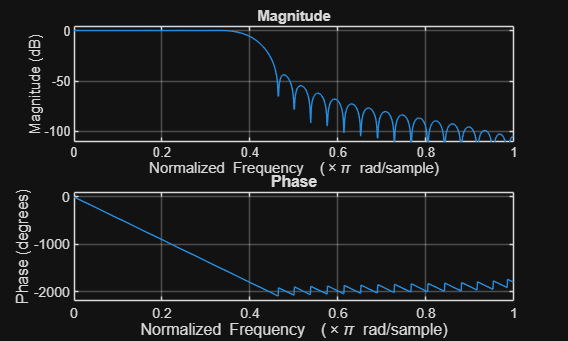


% Hanning Window
w_hann = hanning(Nf)';
hn_hann = hn .* w_hann;     
hn_hann = hn_hann/sum(hn_hann); % Normalizing
freqz(hn_hann, 1, 1024);

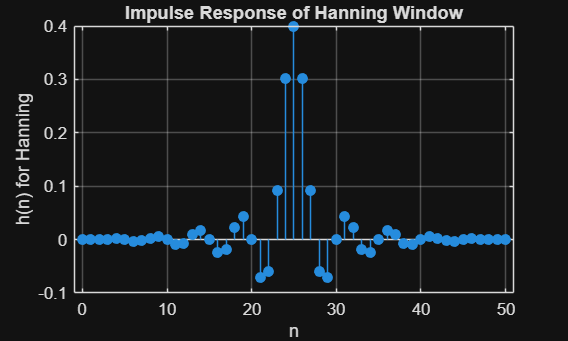


n = 0:length(hn_hann)-1;
stem(n, hn_hann, 'filled')
xlabel('n')
ylabel('h(n) for Hanning')
title('Impulse Response of Hanning Window')
grid on

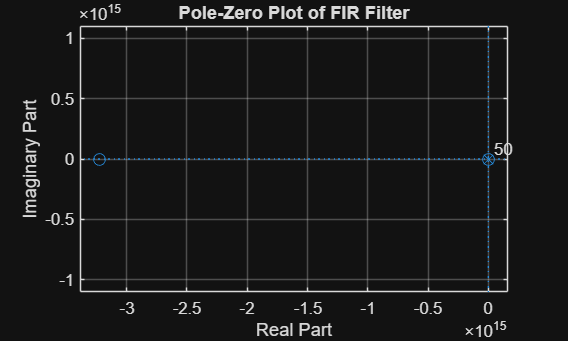


zplane(hn_hann, 1)
title('Pole-Zero Plot of FIR Filter')
grid on

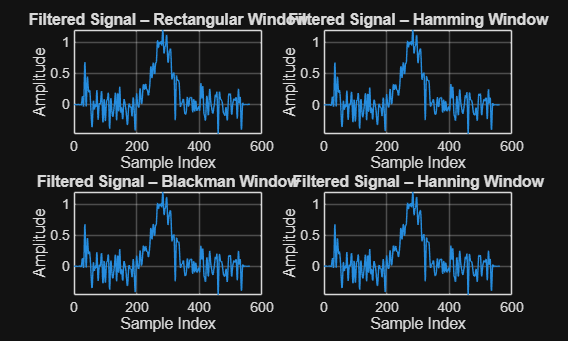


% -----------------------------
% Filter Noise Signal
% -----------------------------

% Rectangular Window
y_rect = conv(hn_rect, y_n_med);
x_rect  = conv(hn_rect,  x_n);
x_rect  = x_rect(length(hn_rect):length(hn_rect)+L-1);
n_rect = 0:length(y_rect)-1;

% Hamming Window
y_hamm = conv(hn_hamm, y_n_med);
x_hamm = conv(hn_hamm,  x_n);
x_hamm = x_hamm(length(hn_hamm):length(hn_hamm)+L-1);
n_hamm = 0:length(y_hamm)-1;

% Blackmann Window
y_black = conv(hn_black, y_n_med);
x_black = conv(hn_black,  x_n);
x_black = x_black(length(hn_black):length(hn_black)+L-1);
n_black = 0:length(y_black)-1;

% Hanning Window
y_hann = conv(hn_hann, y_n_med);
x_hann = conv(hn_hann,  x_n);
x_hann = x_hann(length(hn_hann):length(hn_hann)+L-1);
n_hann = 0:length(y_hann)-1;

figure;

subplot(2,2,1);
plot(n_rect, y_rect);
title('Filtered Signal – Rectangular Window');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

subplot(2,2,2);
plot(n_hamm, y_hamm);
title('Filtered Signal – Hamming Window');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

subplot(2,2,3);
plot(n_black, y_black);
title('Filtered Signal – Blackman Window');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

subplot(2,2,4);
plot(n_hann, y_hann);
title('Filtered Signal – Hanning Window');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

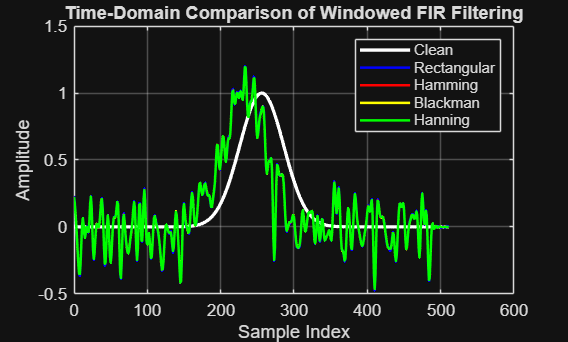


% -----------------------------
% Trimming Convolution Output
% -----------------------------

y_rect_valid  = y_rect(length(hn_rect)  : length(hn_rect)  + L - 1);
y_hamm_valid  = y_hamm(length(hn_hamm)  : length(hn_hamm)  + L - 1);
y_black_valid = y_black(length(hn_black): length(hn_black)+ L - 1);
y_hann_valid  = y_hann(length(hn_hann)  : length(hn_hann)  + L - 1);

% -----------------------------
% Time Domain Comparison
% -----------------------------

n_valid = 0:L-1;

figure;

% Plot clean signal once
plot(n_valid, x_n, 'w', 'LineWidth', 2); hold on;  

% Plot filtered signals
plot(n_valid, y_rect_valid, '-b', 'LineWidth', 1.5);   
plot(n_valid, y_hamm_valid, '-r', 'LineWidth', 1.5);   
plot(n_valid, y_black_valid, '-y', 'LineWidth', 1.5);  
plot(n_valid, y_hann_valid, '-g', 'LineWidth', 1.5);   

legend('Clean','Rectangular','Hamming','Blackman','Hanning');

xlabel('Sample Index');
ylabel('Amplitude');
title('Time-Domain Comparison of Windowed FIR Filtering');
grid on;

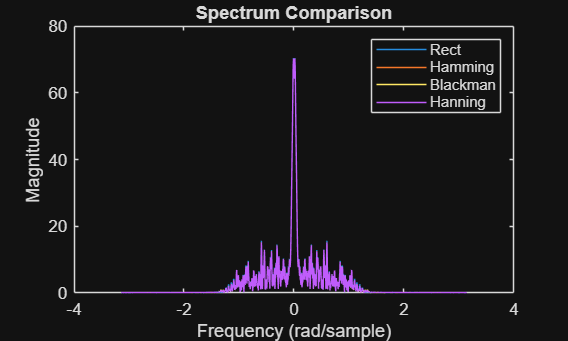


% -----------------------------
% Frequency Domain Comparison
% -----------------------------

Nfft = 1024;
Y_rect = fft(y_rect_valid, Nfft);
Y_hamm = fft(y_hamm_valid, Nfft);
Y_black = fft(y_black_valid, Nfft);
Y_hann = fft(y_hann_valid, Nfft);

w = linspace(-pi, pi, Nfft);

figure;
plot(w, fftshift(abs(Y_rect))); hold on;
plot(w, fftshift(abs(Y_hamm)));
plot(w, fftshift(abs(Y_black)));
plot(w, fftshift(abs(Y_hann)));
legend('Rect','Hamming','Blackman','Hanning');
xlabel('Frequency (rad/sample)');
ylabel('Magnitude');
title('Spectrum Comparison');

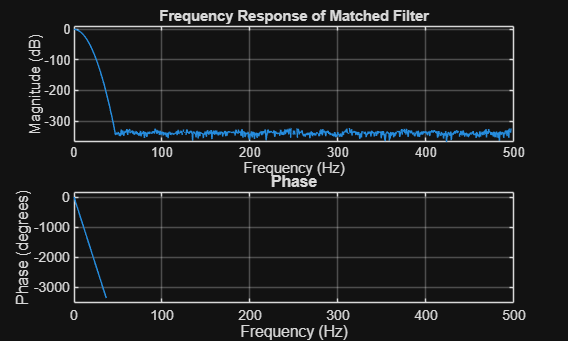


% -----------------------------
% Matched Filter Design
% -----------------------------
h_match = fliplr(x_n);           % Matched filter impulse response
h_match = h_match / sum(h_match);      % Normalize

% -----------------------------
% Matched Filter Analysis
% -----------------------------

figure;
freqz(h_match,1,1024,fs);
title('Frequency Response of Matched Filter');

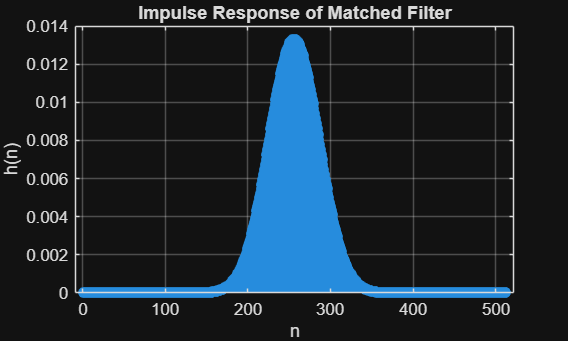


figure;
stem(h_match,'filled');
xlabel('n');
ylabel('h(n)');
title('Impulse Response of Matched Filter');
grid on;

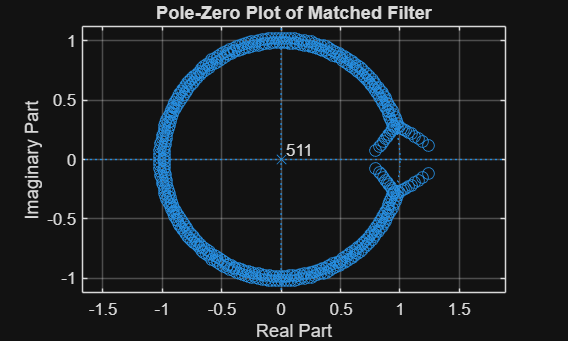


figure;
zplane(h_match,1);
title('Pole-Zero Plot of Matched Filter');
grid on;

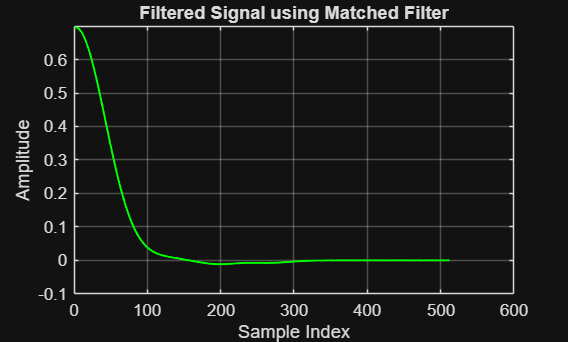


% -----------------------------
% Filtering
% -----------------------------

y_match = conv(y_n_med, h_match);
x_match = conv(x_n, h_match);

L = length(x_n);
y_match_valid = y_match(length(h_match):length(h_match)+L-1);
x_match_valid = x_match(length(h_match):length(h_match)+L-1);

% -----------------------------
% Filtered Signal Plot
% -----------------------------

figure;
plot(y_match_valid,'g','LineWidth',1.2);
xlabel('Sample Index');
ylabel('Amplitude');
title('Filtered Signal using Matched Filter');
grid on;

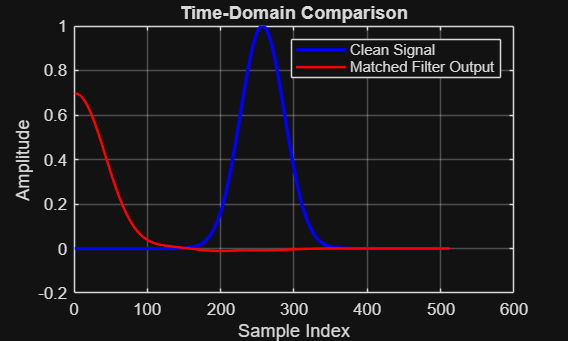


% -----------------------------
% Time Domain Comparison
% -----------------------------
figure;
plot(x_n,'b','LineWidth',2); hold on;
plot(y_match_valid,'r','LineWidth',1.5);
legend('Clean Signal','Matched Filter Output');
xlabel('Sample Index');
ylabel('Amplitude');
title('Time-Domain Comparison');
grid on;

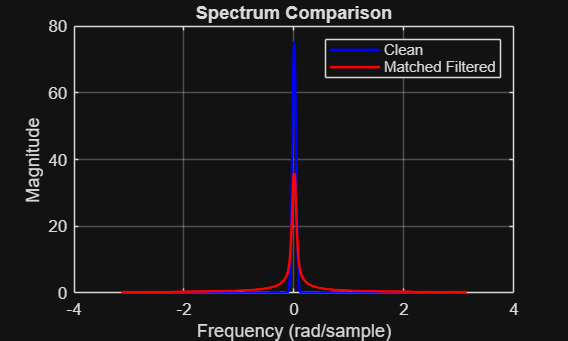


% -----------------------------
% Frequency Domain Comparison
% -----------------------------
X = fftshift(abs(fft(x_n,Nfft)));
Ymatch = fftshift(abs(fft(y_match_valid,Nfft)));
w = linspace(-pi,pi,Nfft);

figure;
plot(w,X,'b','LineWidth',1.5); hold on;
plot(w,Ymatch,'r','LineWidth',1.5);
legend('Clean','Matched Filtered');
xlabel('Frequency (rad/sample)');
ylabel('Magnitude');
title('Spectrum Comparison');
grid on;


% -----------------------------
% SNR Comparison
% -----------------------------

% Noise estimation
n_b = y_n - x_n;

n_a_rect  = y_rect_valid  - x_rect;
n_a_hamm  = y_hamm_valid  - x_hamm;
n_a_black = y_black_valid - x_black;
n_a_hann  = y_hann_valid  - x_hann;
n_a_match = y_match_valid - x_match_valid;

% Power calculation
Ps = mean(x_n.^2);

Pn_before = mean(n_b.^2);
Pn_rect   = mean(n_a_rect.^2);
Pn_hamm   = mean(n_a_hamm.^2);
Pn_black  = mean(n_a_black.^2);
Pn_hann   = mean(n_a_hann.^2);
Pn_match = mean(n_a_match.^2);

% SNR calculation
SNR_before = 10*log10(Ps / Pn_before);
SNR_rect   = 10*log10(Ps / Pn_rect);
SNR_hamm   = 10*log10(Ps / Pn_hamm);
SNR_black  = 10*log10(Ps / Pn_black);
SNR_hann   = 10*log10(Ps / Pn_hann);
SNR_match   = 10*log10(Ps / Pn_match);

% Display
fprintf('\nSNR Comparison Results:\n');


SNR Comparison Results:


fprintf('Before Filtering : %.2f dB\n', SNR_before);

Before Filtering : -0.44 dB


fprintf('Rectangular      : %.2f dB\n', SNR_rect);

Rectangular      : 6.86 dB


fprintf('Hamming          : %.2f dB\n', SNR_hamm);

Hamming          : 7.02 dB


fprintf('Blackman         : %.2f dB\n', SNR_black);

Blackman         : 7.05 dB


fprintf('Hanning          : %.2f dB\n', SNR_hann);

Hanning          : 7.04 dB


fprintf('Matched          : %.2f dB\n', SNR_match);

Matched          : 31.83 dB
